syms K A u_r u_l  DJK DJI u_i u_j u_k u_m
F = (- 0.5*DJK*(u_j - u_i) + 0.5*DJI*(u_j - u_k));

## **The expression for DIJ is defined as follow:**

# 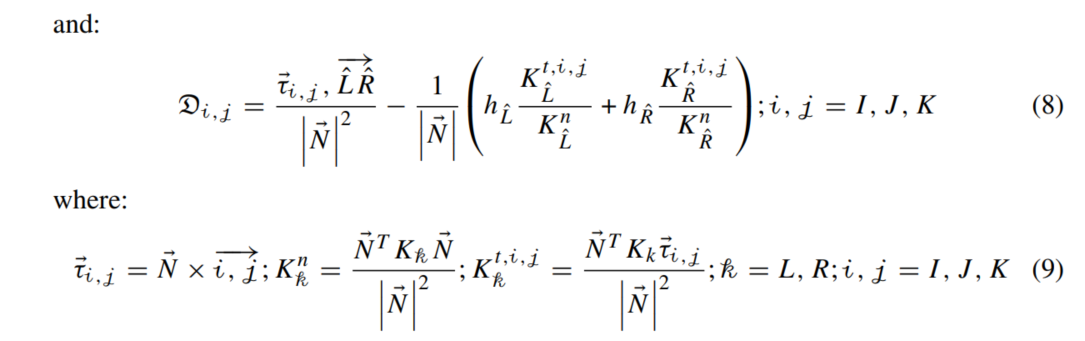

# **Total Flux Expression for Tetrahedron**

**The generalization of the TPFA terms of the MPFA-D is trivial. Therefore, we only need to study the CDT terms.**

**We start by defining the CDT terms of two tetrahedron sharing a common face IJK**

#### **IJK**

Fm = -K*A*collect(F,[u_r u_l u_i u_j u_k])

$$Fm = -A\,K\,\left(\frac{\mathrm{DJK}}{2}\,u_{i}+\left(\frac{\mathrm{DJI}}{2}-\frac{\mathrm{DJK}}{2}\right)\,u_{j}+\left(-\frac{\mathrm{DJI}}{2}\right)\,u_{k}\right)$$

n=3;

The idea here is to generalize is to devide the area A of a polygon using as an auxiliary node the center of A. This way, for instance, we can divide in 3 parts.

## Flux in ICJ

**ICJ**

syms DCK DCM DCJ DCI DCJ u_c A_1 A_2 A_3 A_4
% I J
F_1 = (-0.5*DCJ*(u_c - u_i) + 0.5*DCI*(u_c - u_j));
F_IJ = -K*(A/3)*collect(F_1,[u_r u_l u_i u_c u_j])

$$F\_IJ = -\frac{A\,K\,\left(\frac{\mathrm{DCJ}}{2}\,u_{i}+\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCJ}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCI}}{2}\right)\,u_{j}\right)}{3}$$

## Flux in JCK

**JCK**

F_2 = (- 0.5*DCK*(u_c - u_j) + 0.5*DCJ*(u_c - u_k));
F_JK = -K*(A/3)*collect(F_2,[u_r u_l u_j u_c u_k u_m])

$$F\_JK = -\frac{A\,K\,\left(\frac{\mathrm{DCK}}{2}\,u_{j}+\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCK}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCJ}}{2}\right)\,u_{k}\right)}{3}$$

## Flux in KCI

**KCI**

F_3 = (- 0.5*DCI*(u_c - u_k) + 0.5*DCK*(u_c - u_i));
F_KI = -K*(A/3)*collect(F_3,[u_k u_c u_i])

$$F\_KI = -\frac{A\,K\,\left(\frac{\mathrm{DCI}}{2}\,u_{k}+\left(\frac{\mathrm{DCK}}{2}-\frac{\mathrm{DCI}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCK}}{2}\right)\,u_{i}\right)}{3}$$

## FLUX CDT 

**IJKM**

**F = F_IJ + F_JK + F_KI**

**where**

$A$** = **$A_1 + A_2 + A_3$

%K I
%disp("K I")
F_total =  F_IJ + F_JK + F_KI

$$F\_total = -\frac{A\,K\,\left(\frac{\mathrm{DCJ}}{2}\,u_{i}+\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCJ}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCI}}{2}\right)\,u_{j}\right)}{3}-\frac{A\,K\,\left(\frac{\mathrm{DCI}}{2}\,u_{k}+\left(\frac{\mathrm{DCK}}{2}-\frac{\mathrm{DCI}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCK}}{2}\right)\,u_{i}\right)}{3}-\frac{A\,K\,\left(\frac{\mathrm{DCK}}{2}\,u_{j}+\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCK}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCJ}}{2}\right)\,u_{k}\right)}{3}$$

%F_total = collect(expand(F_total), u_c)
F_n = (1/n)*collect(expand(n*F_total),[u_i,u_j, u_k, u_m, A, K])

$$F\_n = \frac{A\,K\,u_{j}\,\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCK}}{2}\right)}{3}-\frac{A\,K\,u_{i}\,\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCK}}{2}\right)}{3}-\frac{A\,K\,u_{k}\,\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCJ}}{2}\right)}{3}$$

dot(CI,LR) - dot(CK,LR) = dot(CI-CK,LR) = dot(KC+CI) = dot(KI) = dot(-KI)

dot(CJ,LR) - dot(CK,LR) = dot(CJ-CK,LR) = dot(KC+CJ) = dot(KJ) = dot(-KJ)

dot(CI,LR) - dot(CJ,LJ) = dot(IJ) = dot(-JI) 

sabendo que

IJ + JK + KI = 0